sessname = '6_240205_150311';
animal = 'rEO_06';

selectedChannels = [93,37]+1; % LEFT - RIGHT Channels from Str.Pir. Number from Neuroscope
% pyramidal_layer_left = 4;
% pyramidal_layer_right = 12;
% sample_rate_LFP = 2000;
% sample_rate = 20000;
forceReload = false;  % to recalculate SWR and theta firing

basepath = fullfile('I:\Dropbox (Yanik Lab)\Localization Manuscript 2024\RAT DATA', animal, sessname);
cd(basepath)


% Output directory
% plotpath = fullfile(basepath, 'FiringCorrelations');
% if ~isfolder(plotpath)
%     mkdir(plotpath);
% end

% Read raw data info 
[rawRecordings,sampleRate,bitScaling,shankMap,siteMap,siteLoc,probePad] = read_prb_file;

num_theta_bins = 18; % bin size = 20 degrees
bin_edges_theta = linspace(-180, 180, num_theta_bins+1);

% Raw data info
raw_file = fullfile(basepath, 'amplifier.dat');  
FileInfo = dir(raw_file);
nChansInRawFile = 128;
num_samples = FileInfo.bytes/(nChansInRawFile * 2); % int16 = 2 bytes

% Map the binary file into memory
RowDat_map_memory_file = memmapfile(char(raw_file), 'Format', 'int16');
totalDataPoints = numel(RowDat_map_memory_file.Data);
samplesPerChannel = totalDataPoints / nChansInRawFile;

% Initialize a matrix to hold the data from the selected channels
LFPFromSelectedChannels = zeros(numel(selectedChannels), samplesPerChannel, 'int16');

% Extract data for each selected channel
for i = 1:numel(selectedChannels)
    channelIdx = selectedChannels(i);
    disp(channelIdx)
    LFPFromSelectedChannels(i,:) = RowDat_map_memory_file.Data(channelIdx:nChansInRawFile:end);
end

    94
    38


fprintf('Data loading complete.\n');

Data loading complete.



% Scalwe by the smallest voltage step the ADC can resolve (LSB) – is (2.45 V) / (216) = 37.4 μV.  
% Dividing this LSB level by the RHD2000 amplifier gain of 192
LFPFromSelectedChannels = double(LFPFromSelectedChannels).*bitScaling;  

% Helper time vector
Time_vector_LFP = linspace(0, num_samples./sampleRate, length(LFPFromSelectedChannels));

## Theta analysis 

#### 1. Get the theta state according to the spectrogram

% Find theta epochs
freqlist = [2,20];  % 2-20 Hz
window = 2; % sec
noverlap = window - 1;
f_theta = [6 10];
f_delta = [2 3];

% Theta state determined based on pyramidal layer 
theta_windows = getThetaStates(LFPFromSelectedChannels(1,:),'freqlist',freqlist,'window',window,'noverlap',noverlap, ...
    'num_samples',num_samples,'sample_rate',sampleRate,'f_theta',f_theta,'f_delta',f_delta,'th2d_ratio_threshold',2);
num_theta_windows = length(theta_windows);

#### 2. Extract theta phase 

[thetaPhase, thetaLFP] = getThetaPhase(LFPFromSelectedChannels, 'sample_rate',sampleRate, 'f_theta',f_theta);

#### 3. Remove segments with weak theta

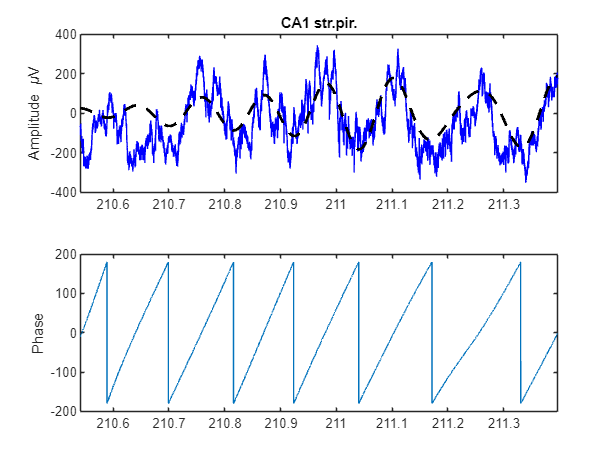

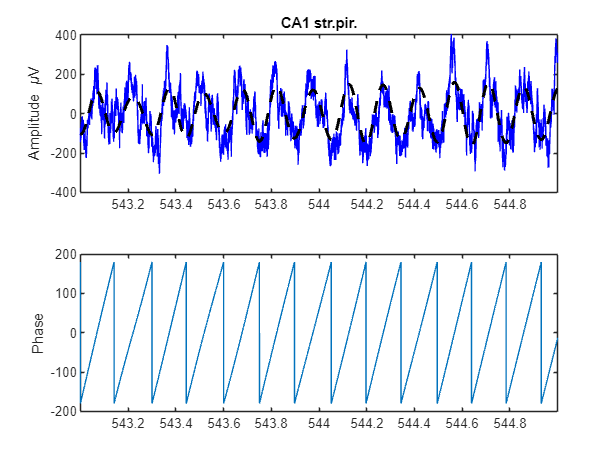

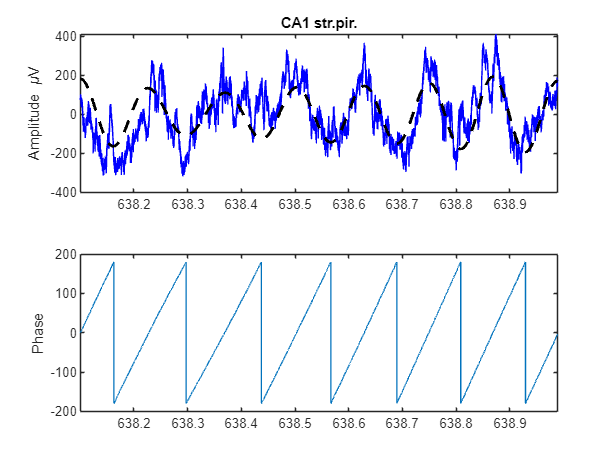

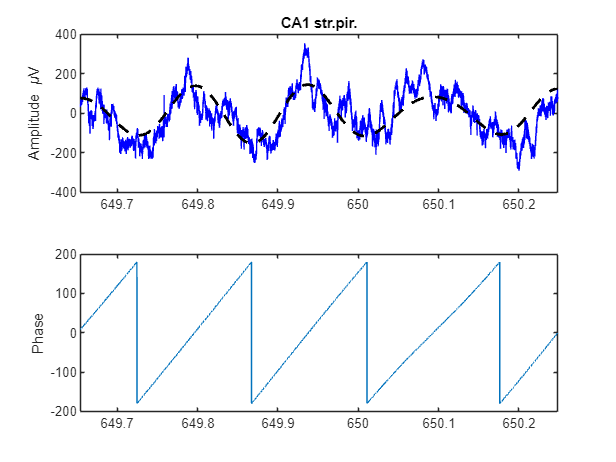

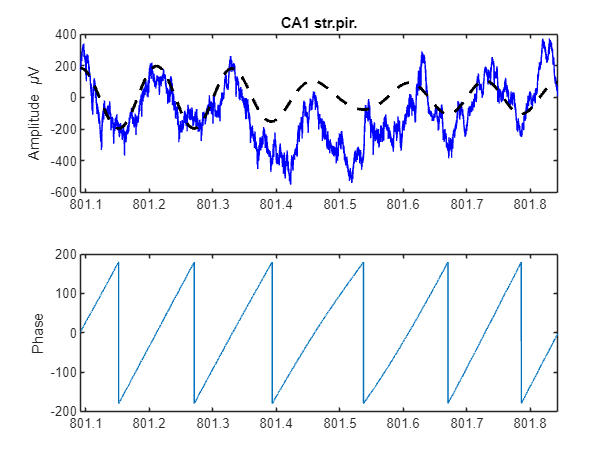

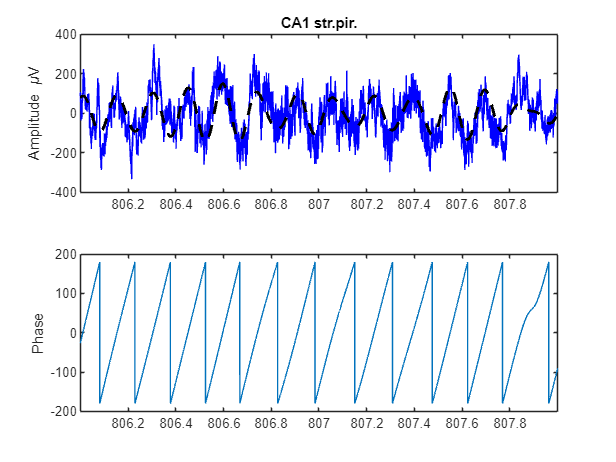

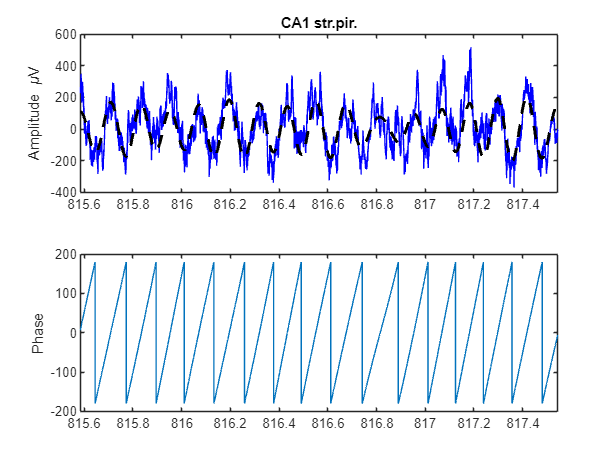

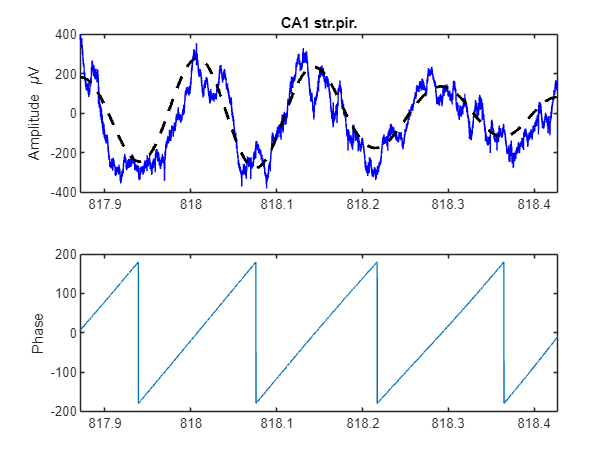

% Find moments where theta is not strong and remove them
new_theta_windows = postprocessThetaSegments(theta_windows, LFPFromSelectedChannels, thetaLFP, thetaPhase, 'phase_threshold',15, ...
    'sample_rate',sampleRate, 'num_samples',num_samples, 'amplitude_threshold',65, 'duration_threshold',0.51, 'channel',1);


num_theta_windows = length(new_theta_windows);

% very_new_theta_windows = testPostprocessThetaSegments(new_theta_windows, LFPFromSelectedChannels, thetaLFP, thetaPhase, 'phase_threshold',15, ...
%     'sample_rate',sampleRate, 'num_samples',num_samples, 'amplitude_threshold',60, 'duration_threshold',0.5);
theta_info.freqs = f_theta;
theta_info.theta_segments = new_theta_windows;
theta_info.thetaLFP = thetaLFP;
theta_info.thetaPhase = thetaPhase;
save(fullfile(basepath, [sessname '.theta_info_new.mat']),'theta_info');

#### 4. Bin firing relative to theta phase

The firing probability is the sum of spikes for each phase bin divided by the sum of spikes during the chosen theta segment. 

% start_theta_sample = arrayfun(@(idx) min(find(theta_windows(idx,1) < Time_vector_LFP & Time_vector_LFP < theta_windows(idx,2))), ...
%     1:num_theta_windows, 'UniformOutput', false);
% stop_theta_sample = arrayfun(@(idx) max(find(theta_windows(idx,1) < Time_vector_LFP & Time_vector_LFP < theta_windows(idx,2))), ...
%     1:num_theta_windows, 'UniformOutput', false);

p_theta = zeros(num_neurons, 1);

Unrecognized function or variable 'num_neurons'.

theta_spikes = zeros(num_neurons, num_theta_bins);
theta_firing_prob = zeros(num_neurons, num_theta_bins);

for c = 1:num_neurons
    % Convert spike times from seconds to sample indices
    spikeIndices = double(spikeTimes(spikeClusters == c));

    % Extract spikes by the start-stop of the theta
    % spikeIndices_selected = arrayfun(@(idx) spikeIndices(find(start_theta_sample{idx} < spikeIndices & spikeIndices < stop_theta_sample{idx})), ...
    %     1:length(theta_windows), 'UniformOutput', false);
    spikeIndices_selected = arrayfun(@(idx) spikeIndices(new_theta_windows(idx,1) < spikeIndices & spikeIndices < new_theta_windows(idx,end)), ...
        1:num_theta_windows, 'UniformOutput', false);

    % Extract theta phase at each spike time
    theta_spike_phases = [];
    win_spikes = zeros(num_theta_windows, num_theta_bins);
    win_firing_prob = zeros(num_theta_windows, num_theta_bins);

    for w = 1:num_theta_windows
        if ~isempty(spikeIndices_selected{w})
            if clusterSites(c) < 65
                spikePhases = thetaPhase(spikeIndices_selected{w},2); % right shank
            else
                spikePhases = thetaPhase(spikeIndices_selected{w},1); % left shank
            end
            win_spikes(w,:) = histcounts(spikePhases, bin_edges_theta);
            win_firing_prob(w,:) = win_spikes(w,:) ./ length(spikeIndices_selected{w});
            theta_spike_phases = [theta_spike_phases spikePhases'];
        end
    end
    theta_phases{c} = theta_spike_phases;
    theta_spikes(c,:) = mean(win_spikes,1);
    theta_firing_prob(c,:) = mean(win_firing_prob,1);
end

% Circular statistics (Rayleigh test)
for c = 1:num_neurons
    if ~isempty(theta_phases{c})
        theta_phases_rad{c} = circ_ang2rad(theta_phases{c});
        p_theta(c) = circ_rtest(theta_phases_rad{c});
    else
        p_theta(c) = NaN;
    end
end

theta_firing.phases = theta_phases; % phase of each spike
theta_firing.phases_rad = theta_phases_rad;
theta_firing.spikes = theta_spikes; % mean number of spikes per bin
theta_firing.firing_prob = theta_firing_prob; % mean firing prob
theta_firing.p_values = p_theta;
theta_firing.num_bins = num_theta_bins;
save(fullfile(basepath, [sessname '.theta_firing_binsize20_new.cellinfo.mat']),'theta_firing');